load("sampleEEGdata.mat");

#### Kernel which looks like an inverted U and a decay function

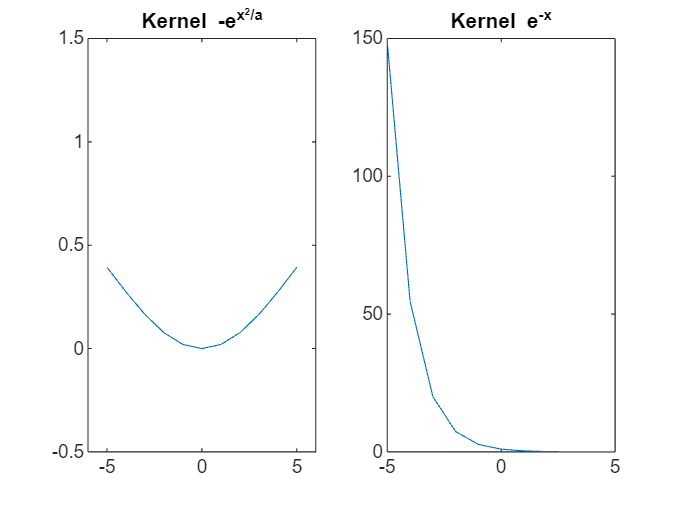

a = 50;
x = -5:1:5;
u_kernel = -exp(-a\x.^2) + 1;

figure;
subplot(121)
plot(x,u_kernel)
title("Kernel -e^{{x^2}/{a}}")
axis([-6 6 -0.5 1.5])
subplot(122)
e_kernel = exp(-x);
plot(x,e_kernel)
title("Kernel e^{-x}")
hold off

### Convolution

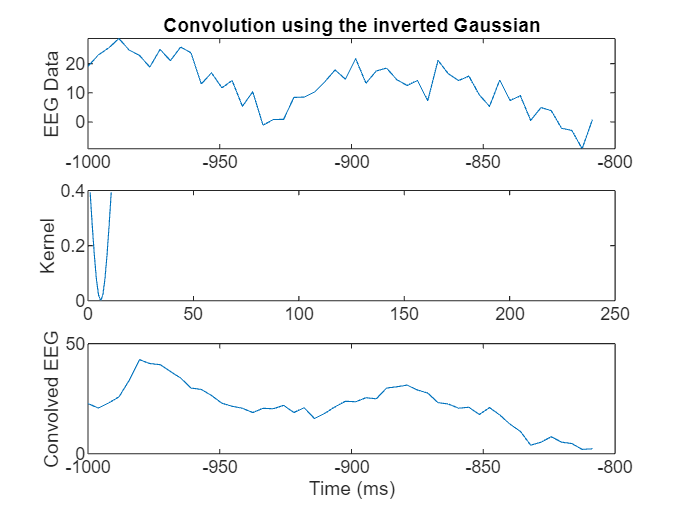

range = 1:50;
signal = EEG.data(3,range,2);
conv_result = conv(signal, u_kernel,"same");

figure;
subplot(311)
plot(EEG.times(range), signal)
title("Convolution using the inverted Gaussian")
ylabel("EEG Data")
subplot(312);
plot(u_kernel)
ylabel("Kernel")
xlim([0 250])
subplot(313)
plot(EEG.times(range), conv_result)
xlabel("Time (ms)")
ylabel("Convolved EEG")

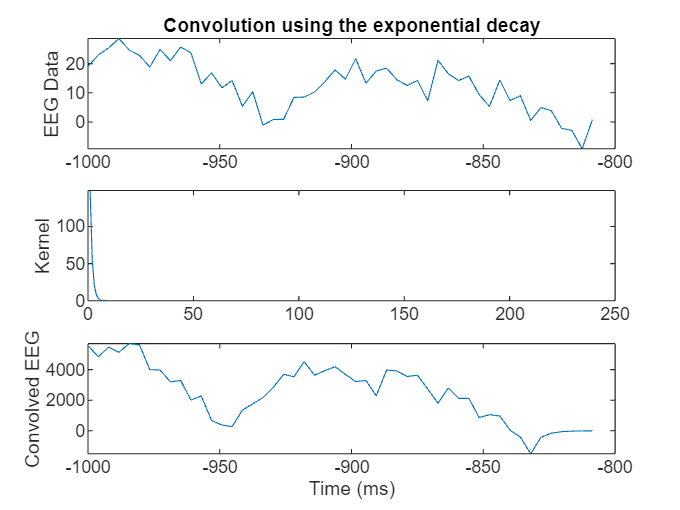

range = 1:50;
signal = EEG.data(3,range,2);
conv_result = conv(signal, e_kernel,"same");

figure;
subplot(311)
plot(EEG.times(range), signal)
title("Convolution using the exponential decay")
ylabel("EEG Data")
subplot(312);
plot(e_kernel)
ylabel("Kernel")
xlim([0 250])
subplot(313)
plot(EEG.times(range), conv_result)
xlabel("Time (ms)")
ylabel("Convolved EEG")